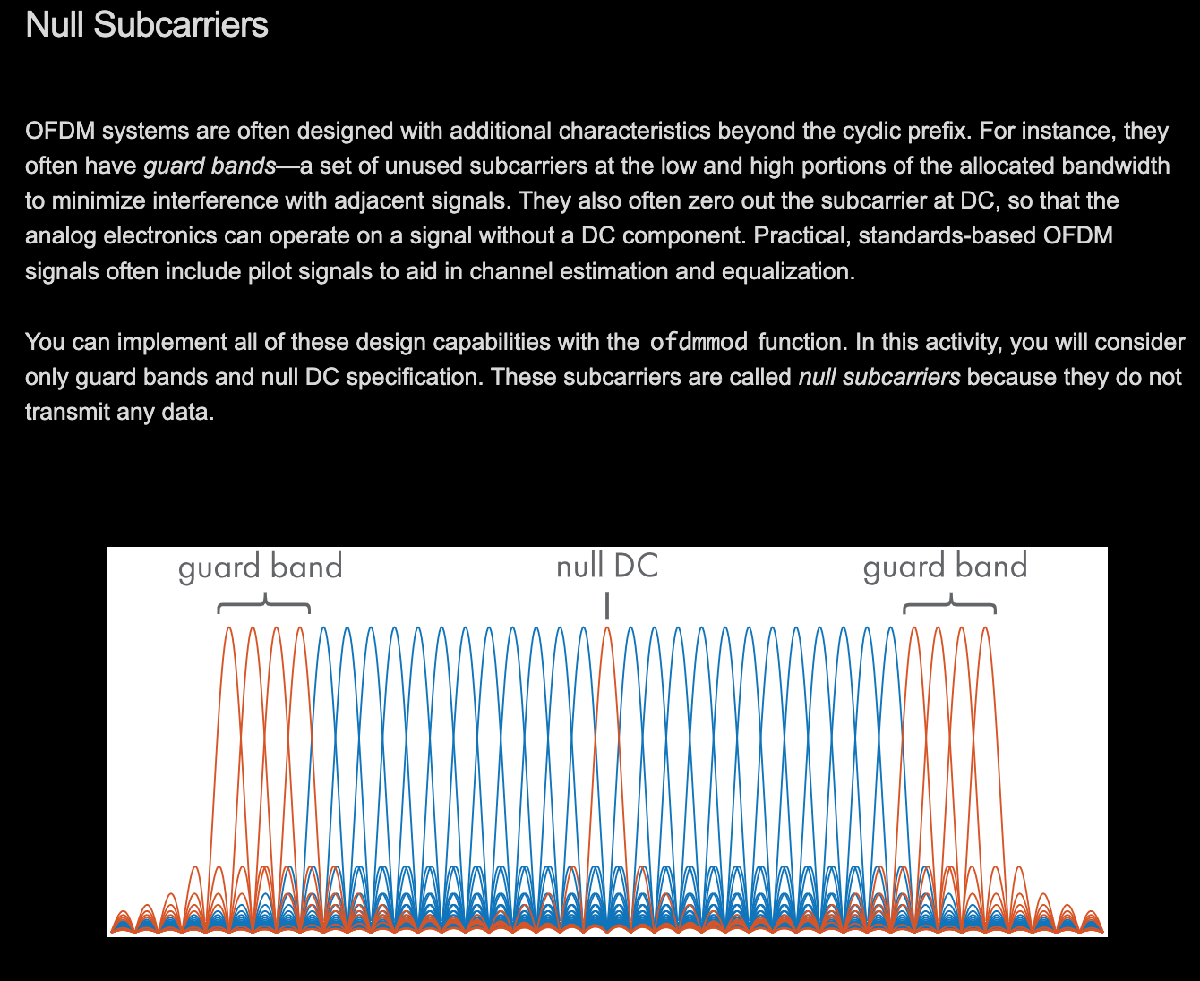

# Null Subcarriers

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets the simulation parameters.

modOrder = 16;  % for 16-QAM
bitsPerSymbol = log2(modOrder)  % modOrder = 2^bitsPerSymbol

mpChan = [0.8; zeros(7,1); -0.5; zeros(7,1); 0.34];  % multipath channel
SNR = 15   % dB, signal-to-noise ratio of AWGN

numCarr = 8192;  % number of subcarriers
cycPrefLen = 32;  % cyclic prefix length

**Background**

In MATLAB, you identify a subcarrier by its index. The subcarriers are numbered from left to right, starting with 1 and ending with `numCarr`. The `ofdmmod` and `ofdmdemod` functions order the subcarriers from the most negative frequencies to the most positive frequencies, with the zero-frequency component in the middle.

To specify the guard band indices, first set the number of subcarriers in each guard band. Then, you can define the guard band indices using the `:` operator. The left guard band indices are defined as follows.

`1``:``numGBCarr`

Similarly, you can define the right guard band indices.

`(``numCarr``-``numGBCarr``+1``)``:``numCarr`

**TASK**

Define the guard band size as `numCarr``/``16` and store it in the variable `numGBCarr`.

Define the left and right guard band indices and store them in the variables `gbLeft` and `gbRight`, respectively.

numGBCarr = numCarr/16;
gbLeft = 1:numGBCarr;
gbRight = (numCarr-numGBCarr+1):numCarr;

The `ofdmmod` function specifies the zero-frequency component in the middle of the frequency range. This means the DC null subcarrier is the center index. When there is an even number of subcarriers, the DC null index is defined as follows.

`numCarr``/``2` `+` `1`

To create the column vector of null subcarrier indices, concatenate the left guard band, DC null, and right guard band indices, and then transpose.

`[``left` `dc` `right``]``'`

**TASK**

Define the DC null index and store it in the variable `dcIdx`.

Create a column vector containing the null subcarrier indices and name it `nullIdx`.

dcIdx = numCarr/2+1
nullIdx = [gbLeft dcIdx gbRight]'

The total number of subcarriers is `numCarr`. However, not all subcarriers are data subcarriers.

This simulation sends one 16-QAM symbol per data subcarrier, which means the length of the source bit sequence is based on the number of data subcarriers.

To determine the number of data subcarriers, subtract the number of null subcarriers from the total number of subcarriers.

The number of source bits to generate is then the number of data subcarriers multiplied by the bits per 16-QAM symbol.

**TASK**

Calculate the number of data subcarriers and store it in the variable `numDataCarr`. Then calculate the number of source bits to generate and store it in the variable `numBits`.

numDataCarr = numCarr-length(nullIdx);
numBits = numDataCarr*bitsPerSymbol


After setting the number of source bits, the script creates the source bit sequence and modulates it using 16-QAM.

srcBits = randi([0,1],numBits,1);
qamModOut = qammod(srcBits,modOrder,"InputType","bit", ...
    "UnitAveragePower",true);

Now you can use the `ofdmmod` function to perform OFDM modulation. To specify the null subcarriers, pass the null index vector as a fourth input.

`sigOut` `=` `ofdmmod``(``sig``,``nCarr``,``cpLen``,``nullIdx``)`

**TASK**

Perform OFDM modulation on the signal `qamModOut`. Specify the number of subcarriers `numCarr`, the cyclic prefix length `cycPrefLen`, and the null subcarrier indices `nullIdx`.

Name the output signal `ofdmModOut`.

ofdmModOut = ofdmmod(qamModOut,numCarr,cycPrefLen,nullIdx)

Next, the OFDM modulated signal is sent over the channel to the receiver.

Channel: multipath and AWGN

mpChanOut = filter(mpChan,1,ofdmModOut);
chanOut = awgn(mpChanOut,SNR,"measured");

Perform OFDM demodulation on the received signal using the `ofdmdemod` function. Because null subcarriers were used, the function needs two additional inputs: the symbol sampling offset and the null index vector.

`sigOut` `=` `ofdmdemod``(``sig``,``nCarr``,``...`

      `cpLen``,``symOffset``,``nullIdx``)`

The symbol sampling offset is the number of signal samples to discard before performing the FFT. It can be any value from 0 to the cyclic prefix length. To remove information corrupted by the multipath channel, it should be larger than the length of the multipath channel impulse response.

**TASK**

Perform OFDM demodulation on the received signal `chanOut`. Specify the number of subcarriers `numCarr`, the cyclic prefix length `cycPrefLen`, and the null subcarrier indices `nullIdx`. For the symbol sampling offset, use the cyclic prefix length `cycPrefLen`.

Name the output signal `ofdmDemodOut`.

sumOffset = cycPrefLen;
ofdmDemodOut = ofdmdemod(chanOut,numCarr, ...
    cycPrefLen,symOffset,nullIdx);

The next step is to equalize the signal.

Transform and shift the channel impulse response with the `fft` and `fftshift` functions as you did previously.

`fftshift``(``fft``(``mpChan``,``numCarr``))`

The channel frequency response has `numCarr` frequency components. However, the OFDM demodulator output contains only the data subcarriers. To perform the element-wise division, you need to remove the null subcarrier frequency components from the channel frequency response.

You can remove specific elements of a vector using indexing.

`x``(``idx``)` `=` `[]`

**TASK**

Transform the multipath channel impulse response `mpChan` to the frequency domain and shift the zero-frequency component to the center of the spectrum. Name the result `mpChanFreq`.

Remove the elements of `mpChanFreq` that correspond to the null subcarrier indices.

mpChanFreq = fftshift(fft(mpChan,numCarr))
mpChanFreq(nullIdx) = [];

**TASK**

Equalize the signal `ofdmDemodOut` by dividing by `mpChanFreq`. Name the equalized signal `eqOut`.

Create a scatter plot of the equalized signal.

eqOut = ofdmDemodOut./mpChanFreq
scatterplot(eqOut)

Congratulations! You've simulated a practical OFDM system with guard bands, null DC, and frequency domain equalizer.

You can visualize the spectra of the transmitted signal and the noisy multipath signal by uncommenting the code at the end of the script. The transmitted OFDM signal is yellow, and the noisy multipath signal is blue. You can see the guard bands and the frequency selective fading from the multipath channel.

Demodulate back into bits, then calculate the BER.
if exist("eqOut","var")  % code runs after you complete Task 7
    qamDemodOut = qamdemod(eqOut,modOrder,"OutputType","bit","UnitAveragePower",true);
    numBitErrors = nnz(srcBits~=qamDemodOut)
    BER = numBitErrors/numBits
end


Further Practice

specAn = dsp.SpectrumAnalyzer("NumInputPorts",2, ...
    "SpectralAverages",50,...
    "ShowLegend",true);
specAn(ofdmModOut,chanOut)


